# Labeling Point Clouds

In order to train an object detector or any supervised deep learning model, you need to first label your data. For this series, we label cars, cones, and barrels using the [Lidar Labeler app](https://www.mathworks.com/help/lidar/ref/lidarlabeler-app.html). 

Before labeling, you may wish to crop your data to only include objects within a certain range. Since these point clouds are large, the point clouds in the 'parkingLot' and 'testData' folders have been cropped using the following limits to the x and y axes:

xMin = -5.06;
xMax = 42.26;
yMin = -23; 
yMax = 23;
zMin = -0.513;
zMax = 10.8586;

You can do this with the LiDAR Viewer app or the [cropPointCloud](matlab:open('./cropPointCloud.m')) function generated from the app. 

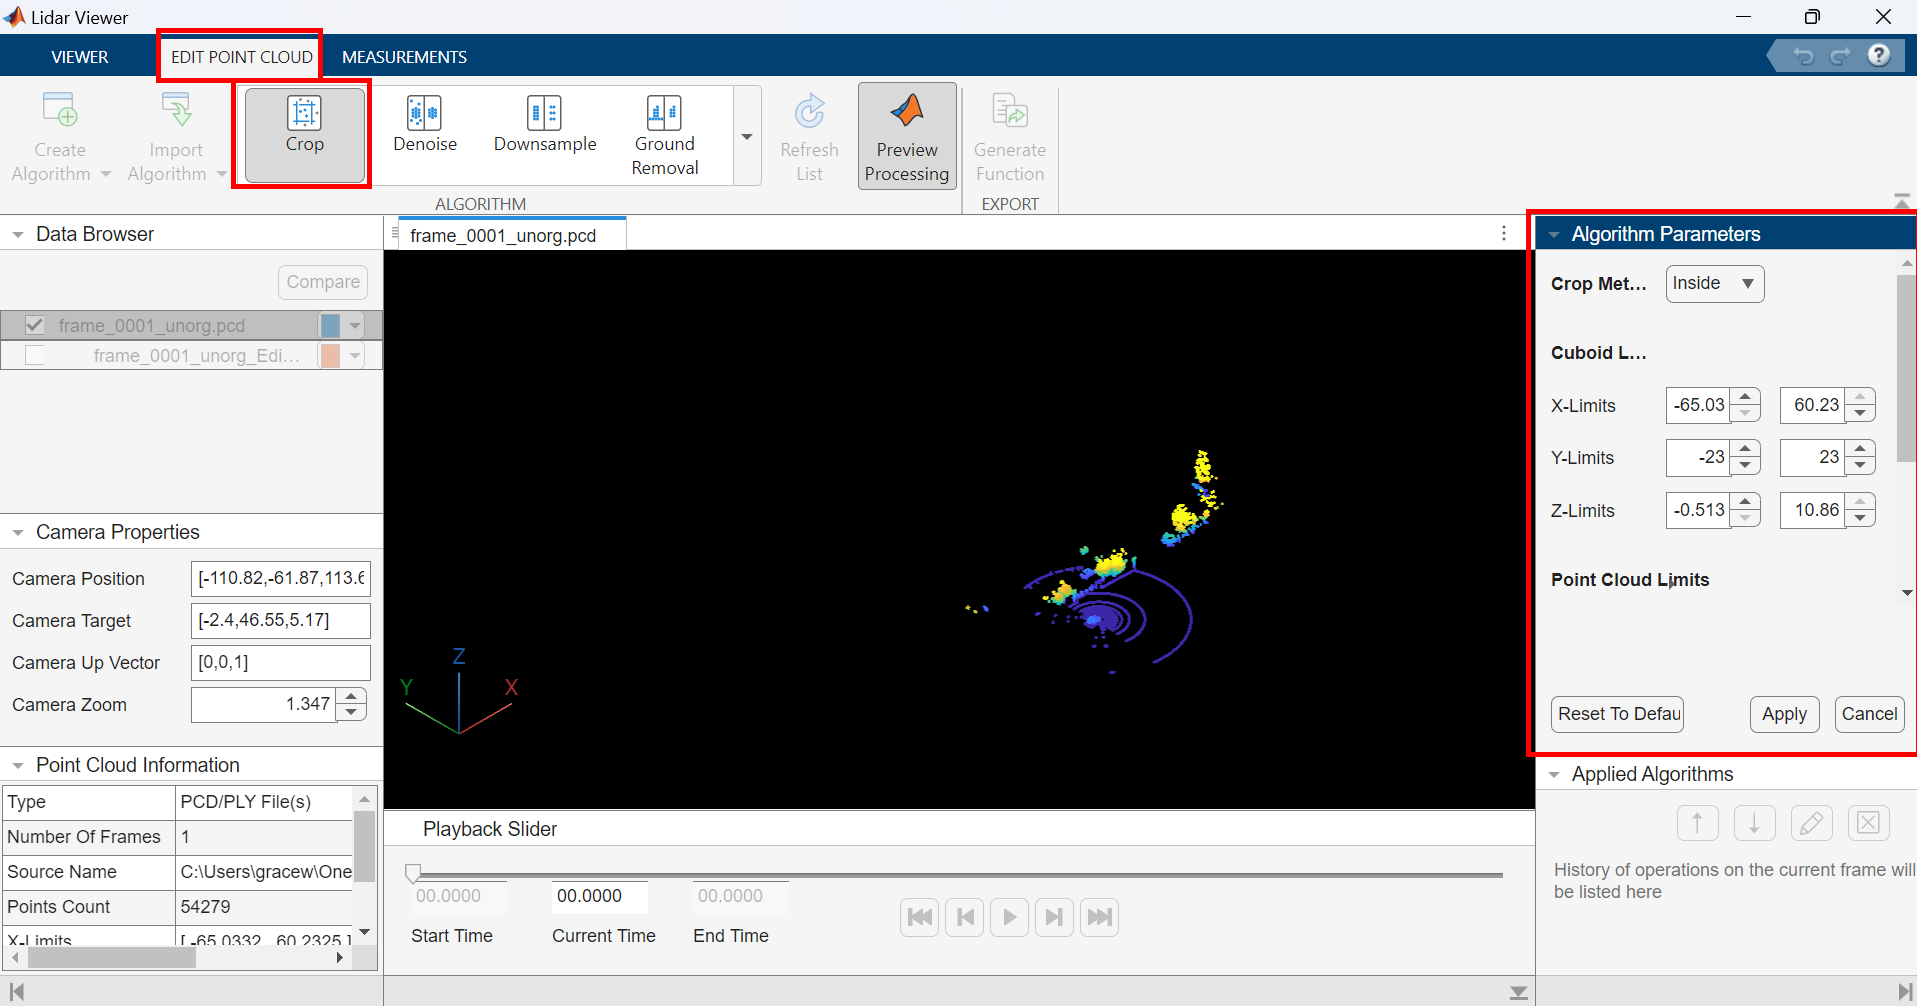

You can start a new labeling session by running the 'lidarLabeler' command below

lidarLabeler

or by selecting the Lidar Labeler app from the 'APPS' tab

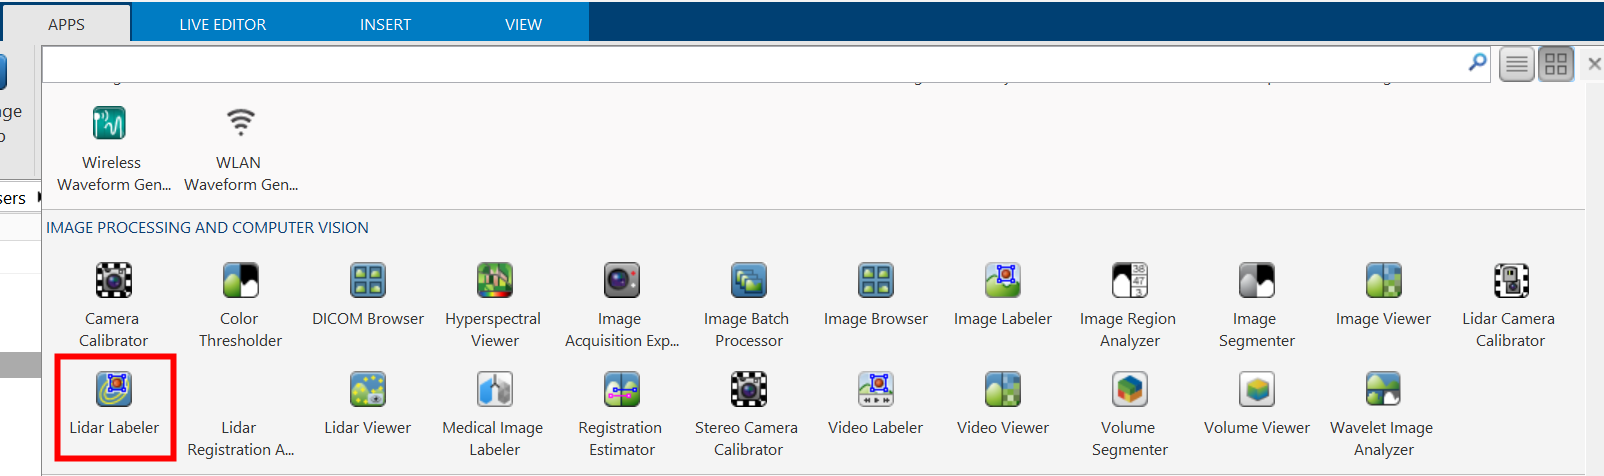

When the applicaiton opens, use the 'Import' button to import the point cloud data and, if applicable, any labels you may have already created. In the video, we import a Point Cloud Sequence through .PCD files, but there are many different data formats and filetypes supported, as shown below.

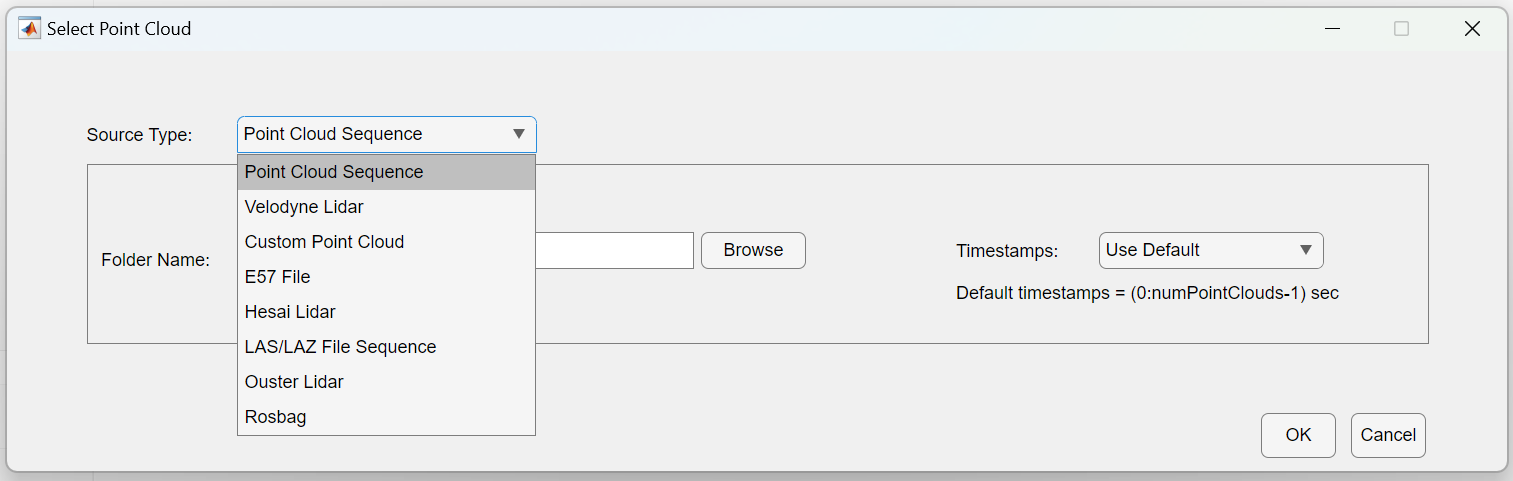

Once you have data loaded into the app, you're ready to start labeling! The options on the toolstrip allow you to change how you see the point cloud or how your bounding boxes are made

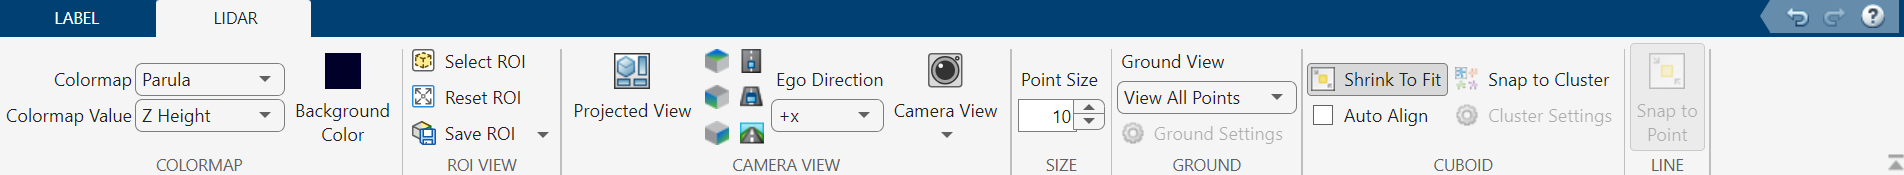

And the 'ROI Labels' Panel to the left will be where you actually create the label definitions

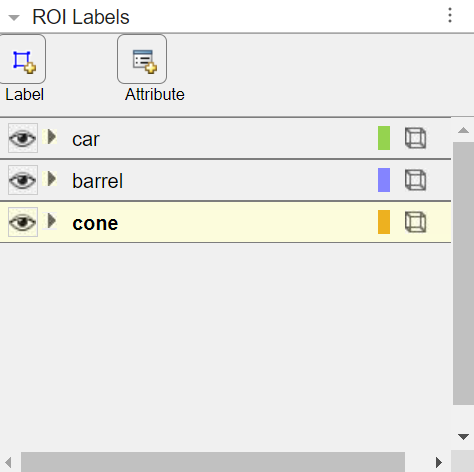

When you're ready to start labeling, simply choose the label you want to use, hover over the desired point cloud with your mouse, and click! A bounding box will automatically be created based on the cluster you had highlighted. 

While using the app, you have the option to save your session so that you can come back and finish labeling later. Doing this will save the location of your data as well as any labels you have created already. 

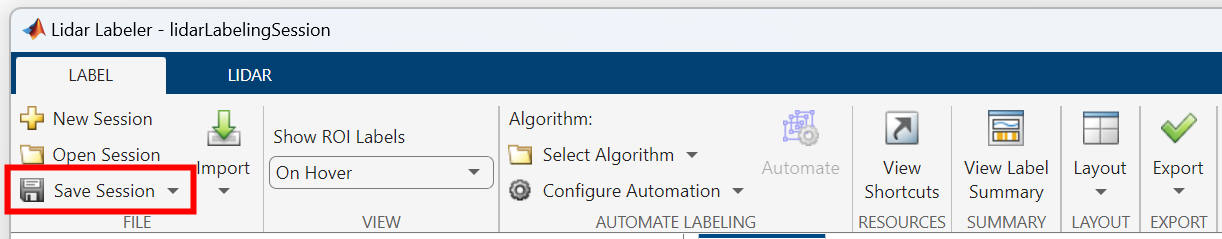

You can open a saved session by passing the name of the .mat file that contains the saved session, as shown below, or by selecting 'Open Session' from the app.

You can also use `groundTruthLidar` objects (often named gTruth) to share the labeling progress with others. First, use the code below to update gTruth so the variable shows where the data is stored on the new computer using the [`changeFilePaths`](https://www.mathworks.com/help/vision/ref/groundtruth.changefilepaths.html) function.

oldPath = gTruth.DataSource.SourceName;
% Fill this in with the location of the parkingLot folder. 
newPath = "";
alternativePaths = {[currentPathPixels newPathPixels]};
unresolvedPaths = changeFilePaths(gTruth,alternativePaths);

Then, open the Lidar Labeler, select 'Import' then 'Labels', then select the modified gTruth